# SASNE running example

data = readmatrix('data/imbalanced_test.txt');

[sasne_out,Z] = SASNE(data);

constructing graph...
Smallest k is 5 in layer 1
Elapsed time is 0.245435 seconds.
computing graph distance...
Elapsed time is 0.179182 seconds.
computing tsne embedding...
Elapsed time is 1.240201 seconds.
Total running time 1.6797 seconds


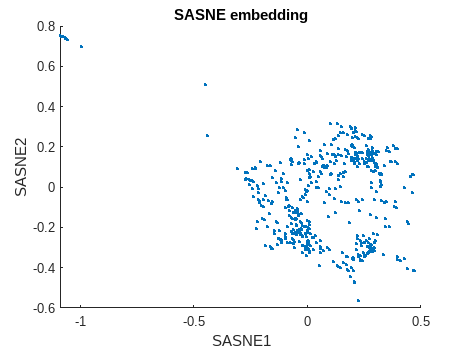

figure
scatter(sasne_out(:,1),sasne_out(:,2),5,'filled')
title('SASNE embedding')
xlabel('SASNE1')
ylabel('SASNE2')

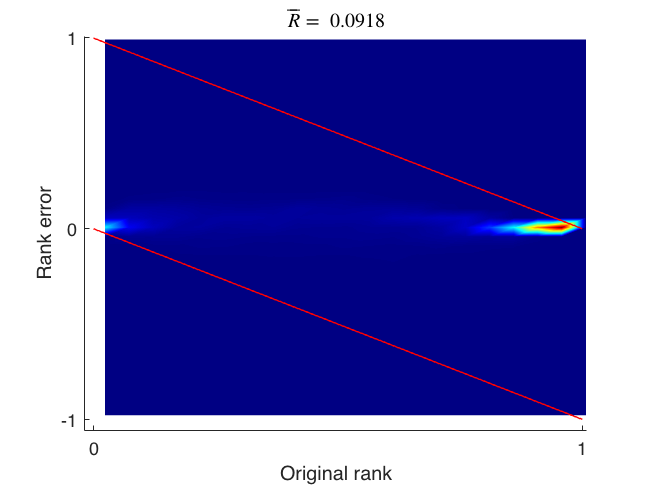

D_original = pdist(Z,'euclidean');
D_sasne = pdist(sasne_out,'euclidean');
RRP(D_original,D_sasne);

clear D_original D_sasne ans